# Assignment 3 - Properties of the Hodgkin-Huxley equations

### 200488E - PUSHPAKUMARA H.M.R.M.

hhconst;

## 1. Threshold

### Question 01

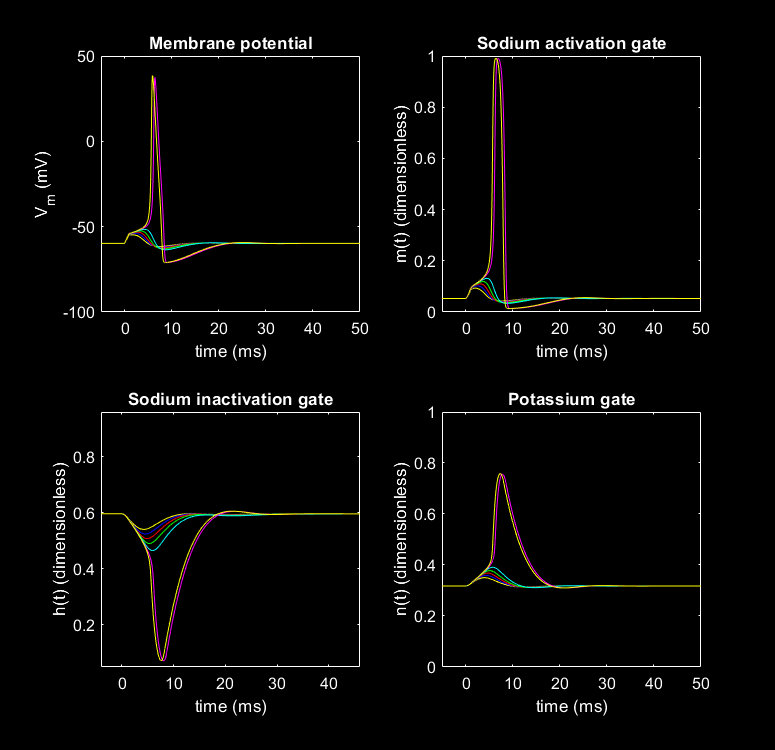

amp1 = 6

amp1 = 6.5000

amp1 = 6.7500

amp1 = 6.8750

amp1 = 6.9375

amp1 = 6.9688

amp1 = 6;
width1 = 1;
hhmplot(0,50,0);

for n = 1:6
    display(amp1);
    amp1 = (amp1+7)/2;
    hhmplot(0,50,n);
end

According to the plots that I have obtained, we can clearly see the amplitueds **below the 6.9375 are not enogh** to pass the treshold value. Amplitudes **above 6.9375 have pass** the treshold value. Therefore, the closest threshold value should be near to 6.9375.  To obtain closest value, I choose some values near to 6.9375.

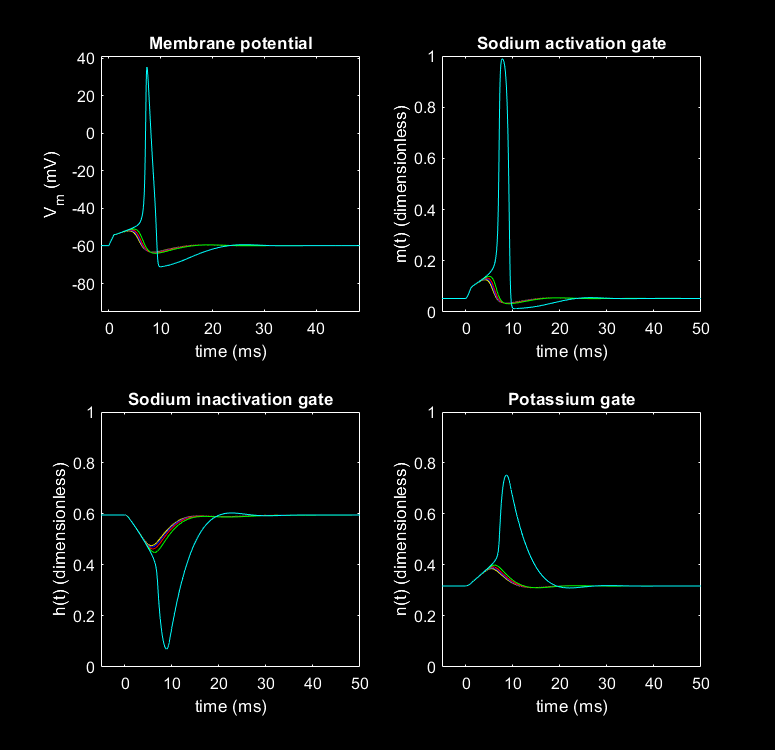

amp1 = 6.9200

amp1 = 6.9300

amp1 = 6.9400

amp1 = 6.9500

amp1 = 6.92;
hhmplot(0,50,0);

for n = 1:4
    display(amp1);
    amp1 = amp1+0.01;
    hhmplot(0,50,n);
end

According to this graphs, we can clearaly see the threshold value is **6.95µAcm^{-2}**.

_

_

_

### Question 02

Let's find    for some different amplitudes .

amp1 = 6.9000

Sum_of_Jie = 6.9000

total_current_densities = 6.8998

*


amp1 = 6.9100

Sum_of_Jie = 6.9100

total_current_densities = 6.9100

*


amp1 = 6.9200

Sum_of_Jie = 6.9200

total_current_densities = 6.9199

*


amp1 = 6.9300

Sum_of_Jie = 6.9300

total_current_densities = 6.9300

*


amp1 = 6.9400

Sum_of_Jie = 6.9400

total_current_densities = 6.9399

*


amp1 = 6.9500

Sum_of_Jie = 6.9500

total_current_densities = 6.9500

*


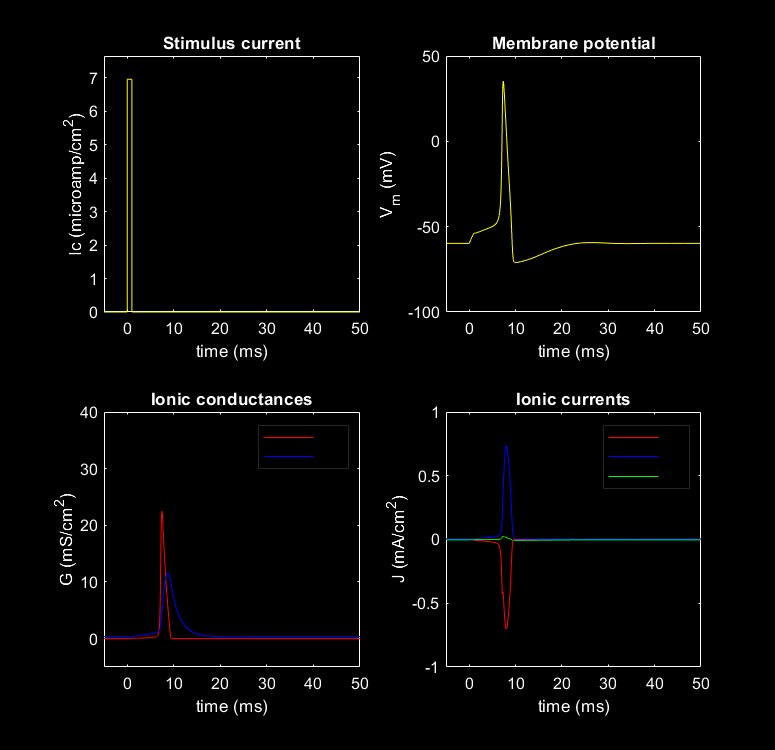

amp1 = 6.9600

Sum_of_Jie = 6.9600

total_current_densities = 6.9620

*


amp1 = 6.90;
for n=1:7
    [qna, qk, ql] = hhsplot (0,50);
    display(amp1);
    Sum_of_Jie = width1*amp1
    total_current_densities = qna+qk+ql
    fprintf('*\n');
    amp1 = amp1+0.01;
end

The last plots are plots when amp1 is in threshold value.

By observing above values, we can say that 

##                                 ʃ Σk Jk dt = ʃ Je dt

_

_

_

## 2. Refractoriness

### Question 03

First, Let's try with the given value for 25ms delay. 

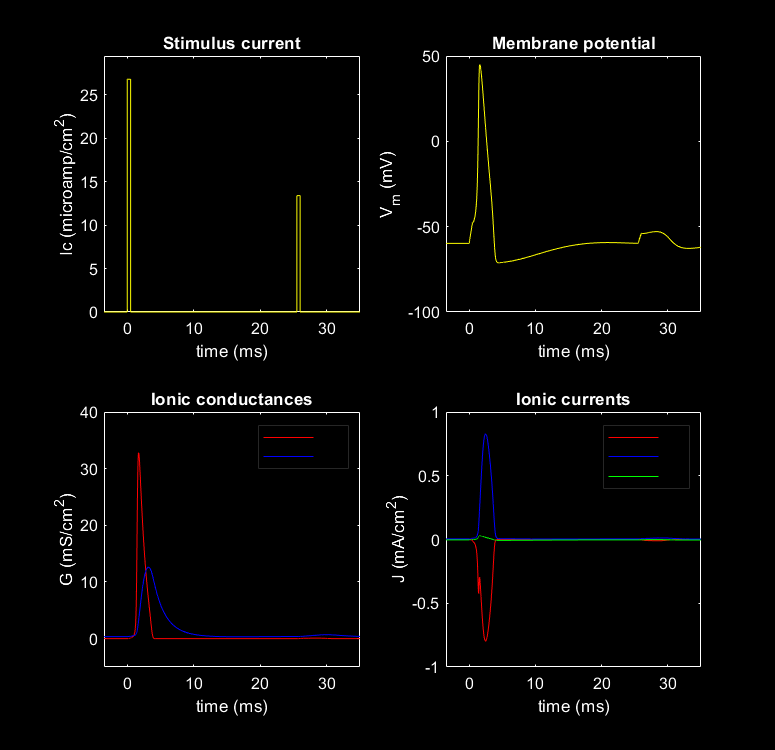

amp1 = 26.8;
width1 = 0.5;
delay2 = 25;
amp2 = 13.4;
width2 = 0.5;
hhsplot(0,35);

Here we can see, 13.4 μAcm^{-2} not enough to generate an action potential.

Let's find the appropriate value for 25ms delay.

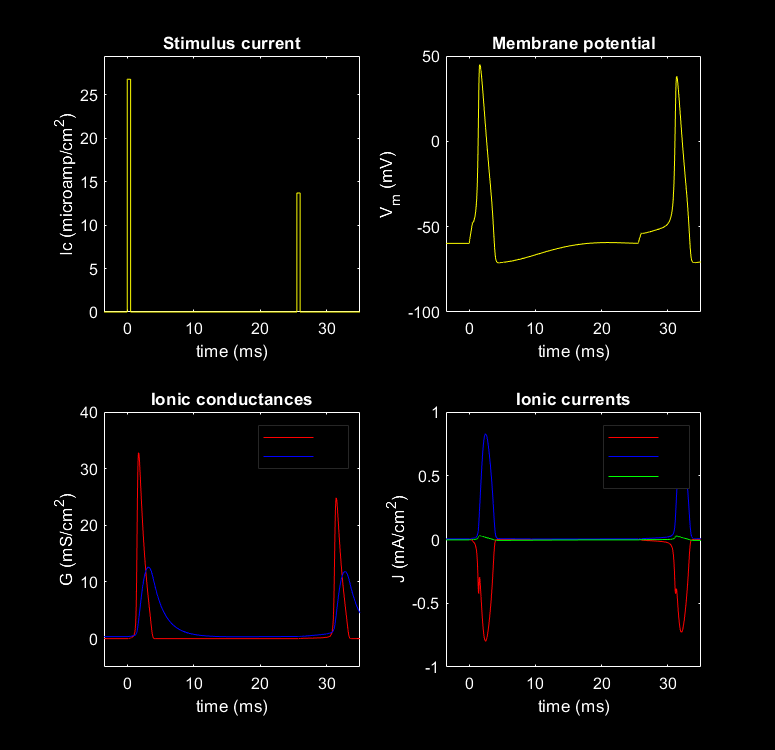

amp1 = 26.8;
width1 = 0.5;
delay2 = 25;
amp2 = 13.7;
width2 = 0.5;
hhsplot(0,35);

Therefore, here we can see, **13.7** μAcm^{-2} should be the second impulse for 25ms delay.

Now Let's find 2nd impulse for 20ms delay.

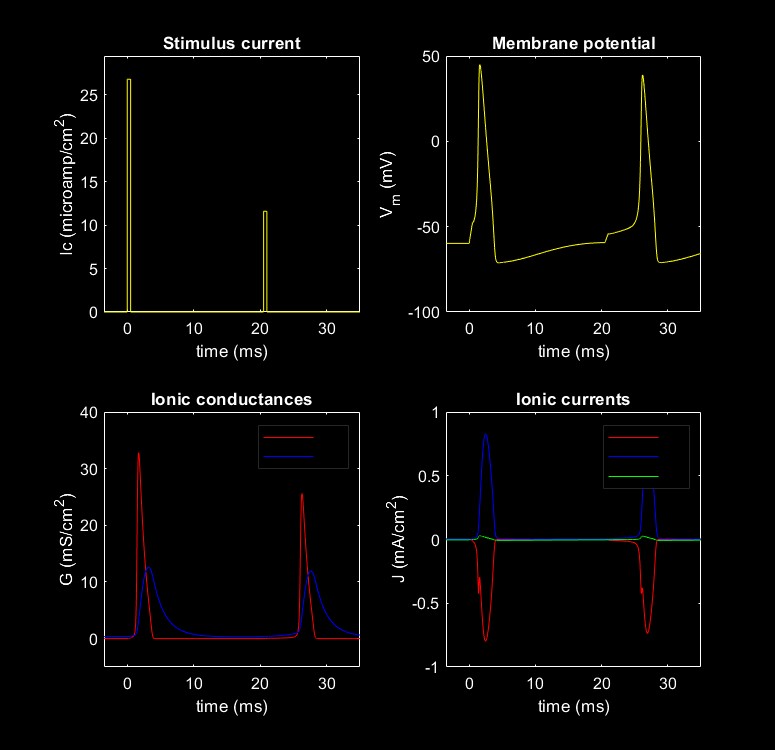

amp1 = 26.8;
width1 = 0.5;
delay2 = 20;
amp2 = 11.6;
width2 = 0.5;
hhsplot(0,35);

Here, the amplitude for the 2nd impulse should be **11.6 **μAcm^{-2}.

Now Let's find 2nd impulse for 18ms delay.

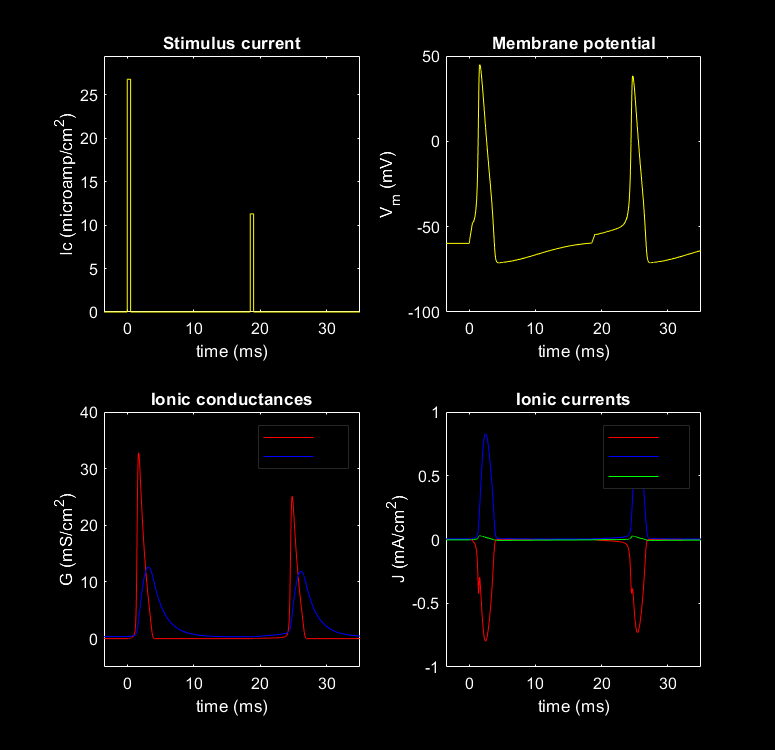

amp1 = 26.8;
width1 = 0.5;
delay2 = 18;
amp2 = 11.3;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **11.3 **μAcm^{-2} when delay is 18ms.

Now Let's find 2nd impulse for 16ms delay.

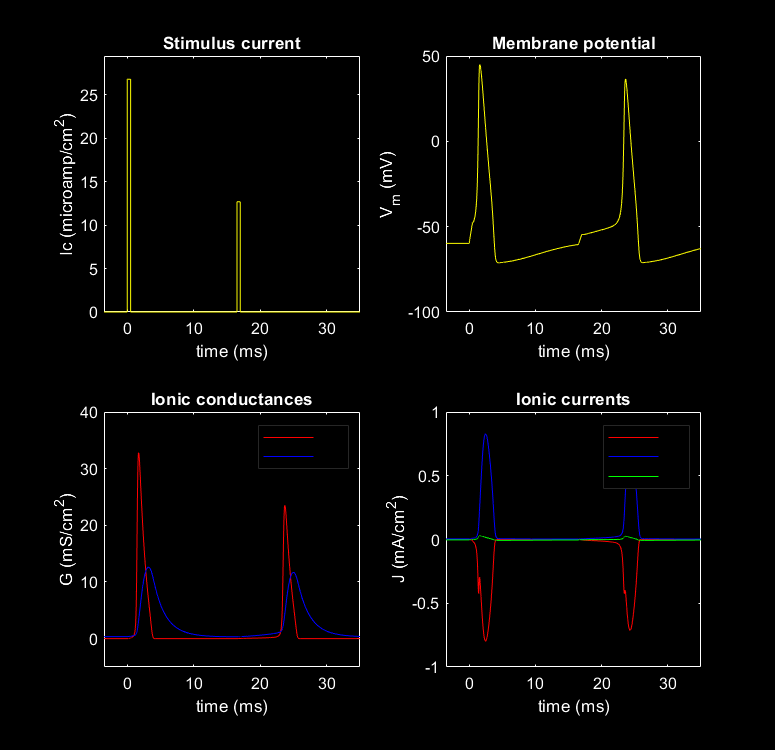

amp1 = 26.8;
width1 = 0.5;
delay2 = 16;
amp2 = 12.7;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **12.7 **μAcm^{-2} when delay is 16ms.

Now Let's find 2nd impulse for 14ms delay.

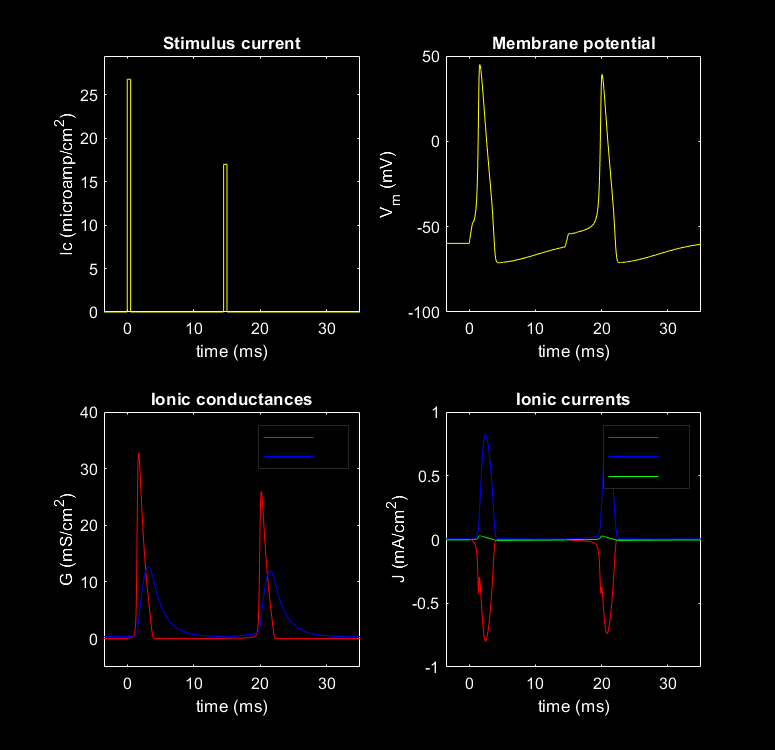

amp1 = 26.8;
width1 = 0.5;
delay2 = 14;
amp2 = 17.0;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **17.0 **μAcm^{-2} when delay is 14ms.

Now Let's find 2nd impulse for 12ms delay.

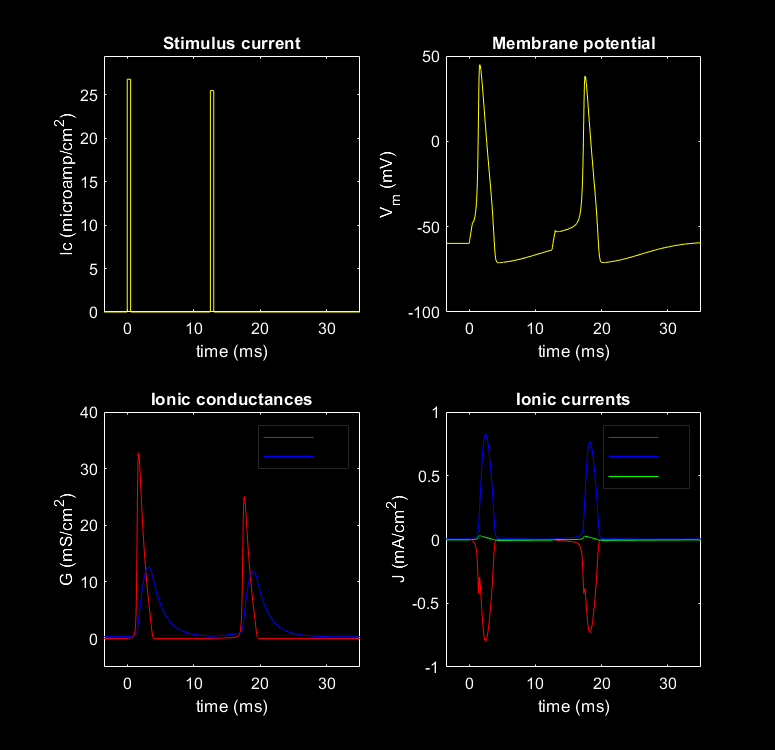

amp1 = 26.8;
width1 = 0.5;
delay2 = 12;
amp2 = 25.5;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **25.5 **μAcm^{-2} when delay is 12ms.

Now Let's find 2nd impulse for 10ms delay.

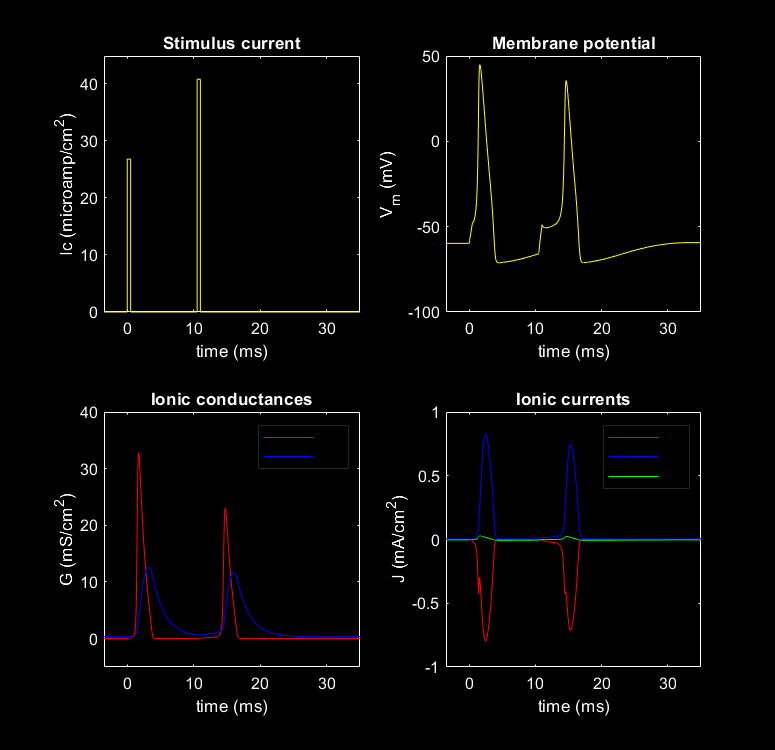

amp1 = 26.8;
width1 = 0.5;
delay2 = 10;
amp2 = 40.8;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **40.8 **μAcm^{-2} when delay is 10ms.

Now Let's find 2nd impulse for 8ms delay.

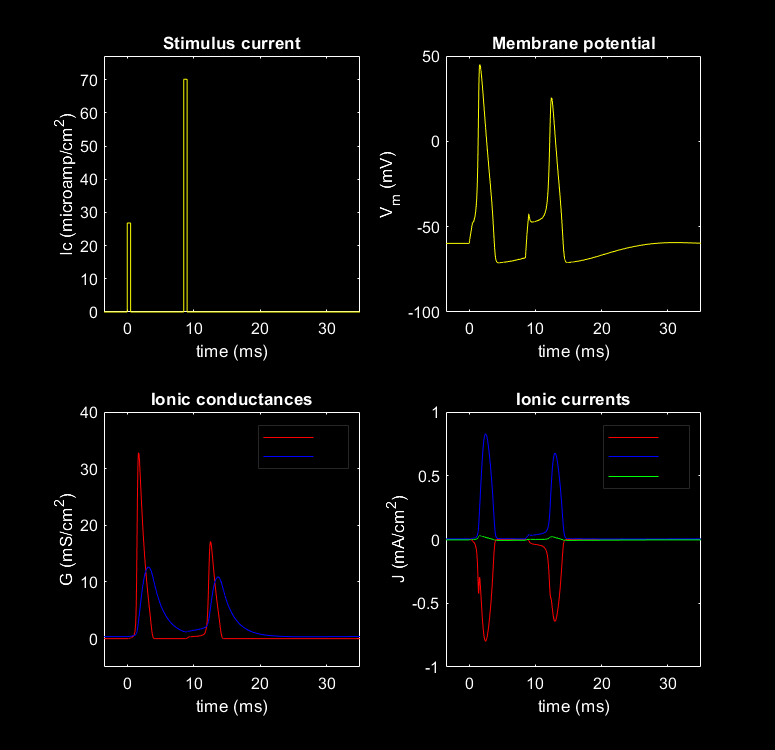

amp1 = 26.8;
width1 = 0.5;
delay2 = 8;
amp2 = 70.1;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **70.1 **μAcm^{-2} when delay is 8ms.

Now Let's find 2nd impulse for 6ms delay.

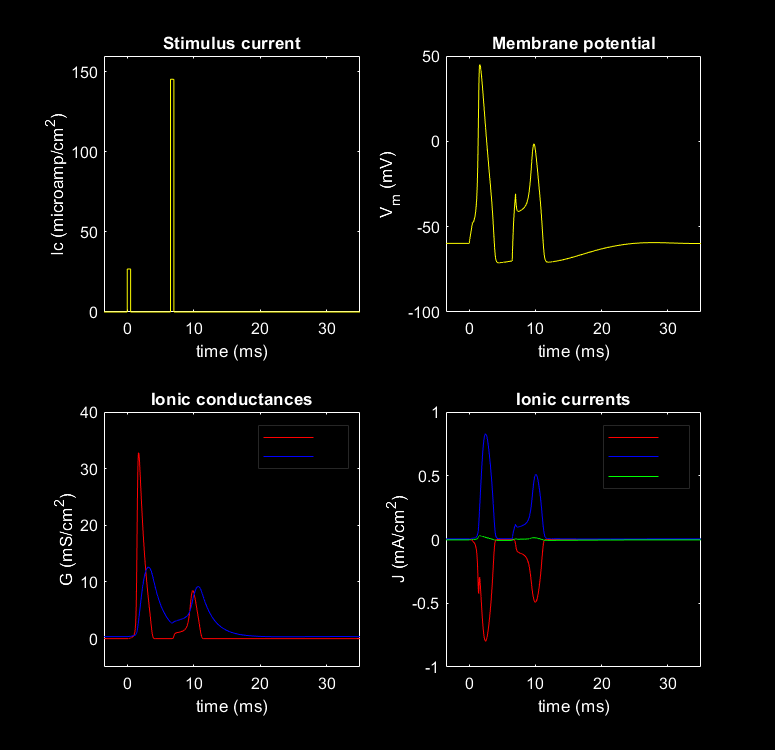

amp1 = 26.8;
width1 = 0.5;
delay2 = 6;
amp2 = 145.2;
width2 = 0.5;
hhsplot(0,35);

Therefore, the amplitude for the 2nd impulse should be **145.2 **μAcm^{-2} when delay is 6ms. But, it also slightly above the zero. deffinitly amplitude should be higer than **145.2 **μAcm^{-2}.

_

**In summery**

delay = [6; 8; 10; 12; 14; 16; 18; 20; 25];
Second_impulse = [145.2; 70.1; 40.8; 25.5; 17.0; 12.7; 11.3; 11.6; 13.7];
Table = table(delay,Second_impulse)

Table = 9×2 table
    delay    Second_impulse
    _____    ______________

      6          145.2     
      8           70.1     
     10           40.8     
     12           25.5     
     14             17     
     16           12.7     
     18           11.3     
     20           11.6     
     25           13.7     


_

_

_

### Question 04

The ratio 𝐼2𝑡ℎ/𝐼1𝑡ℎ as a function of inter-pulse interval

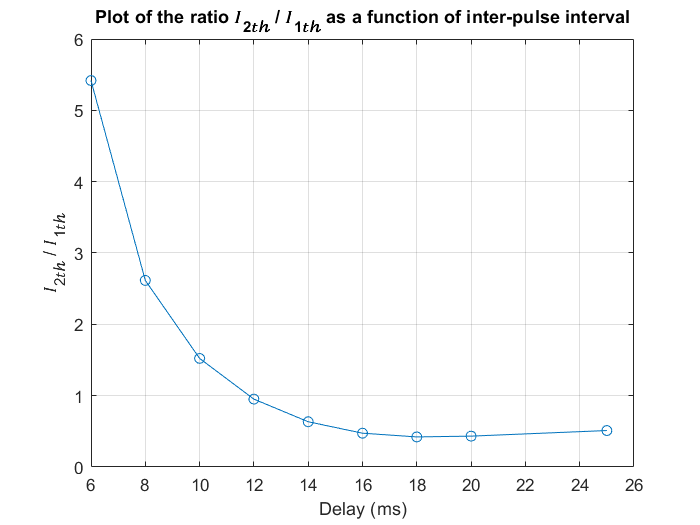

Delays = [6, 8, 10, 12, 14, 16, 18, 20, 25];
Current_ratio = [145.2, 70.1, 40.8, 25.5, 17.0, 12.7, 11.3, 11.6, 13.7]./26.8;
figure;
plot(Delays,Current_ratio,'o-');
xlabel('Delay (ms)')
ylabel('𝐼_{2𝑡ℎ} / 𝐼_{1𝑡ℎ}')
title('Plot of the ratio 𝐼_{2𝑡ℎ} / 𝐼_{1𝑡ℎ} as a function of inter-pulse interval')
grid on

By looking at this graph, we can see that when delay is 6ms, the required current is more than 5 times higher than initial thresold value. Therefore, **absolute refractory period is 0 - 6 ms**.

And also we can see, after 12ms, the required pulse is lower than the initinal threshold value. Therefor, we can say, The **relative refractory period is 6 - 12 ms.**

_

_

_

## **Repetitive activity**

### **Question 05**

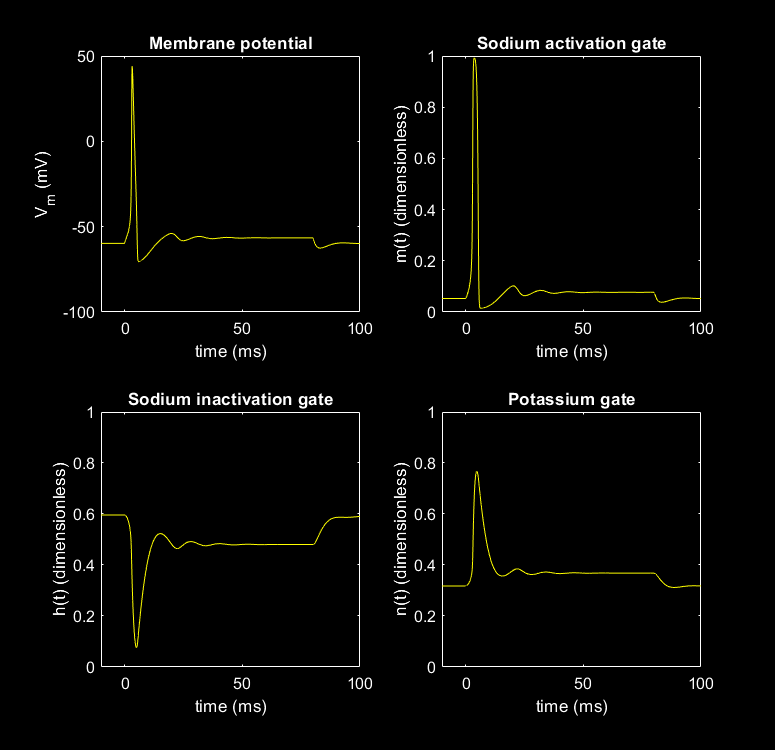

amp1=5;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude = 5

**Number of APs = 1**

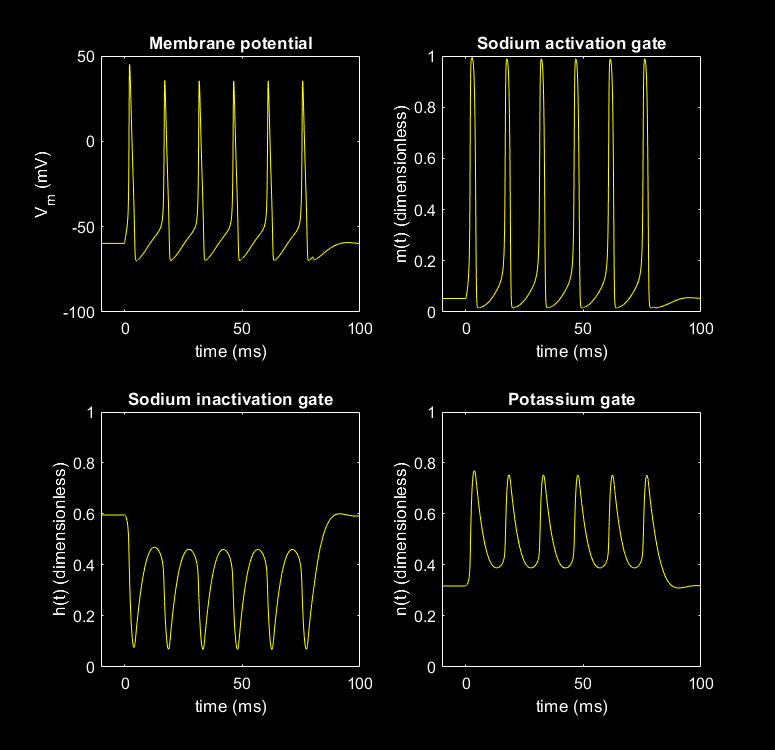

amp1=10;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude =  10

**Number of APs = 6**

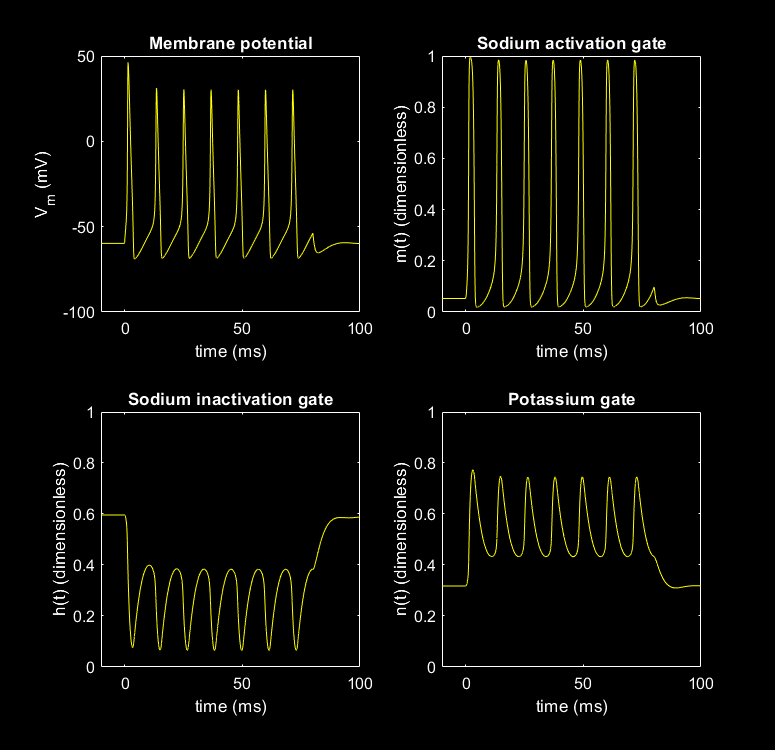

amp1=20;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude = 20

**Number of APs = 7**

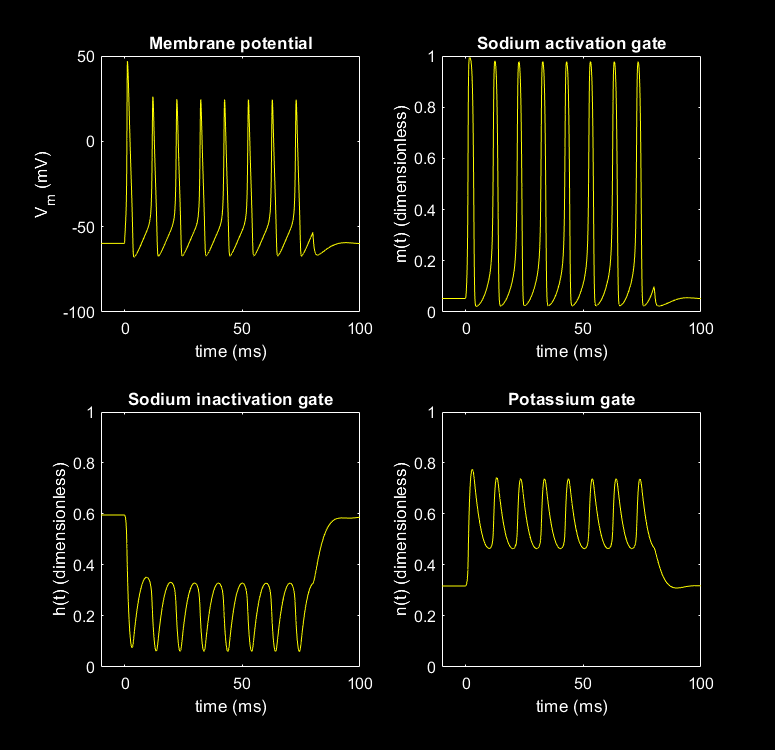

amp1=30;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude = 30

**Number of APs = 8**

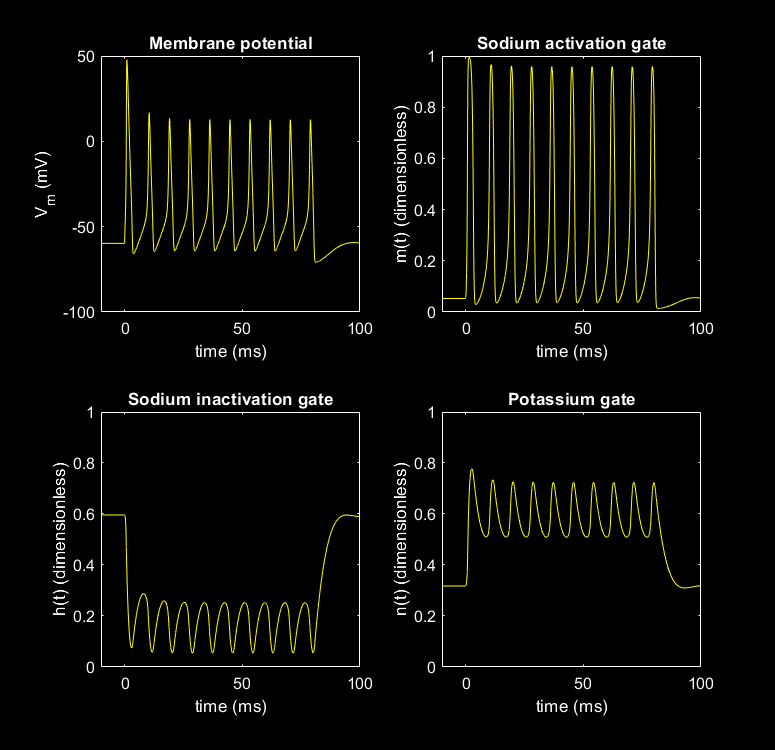

amp1=50;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude = 50

**Number of APs = 10**

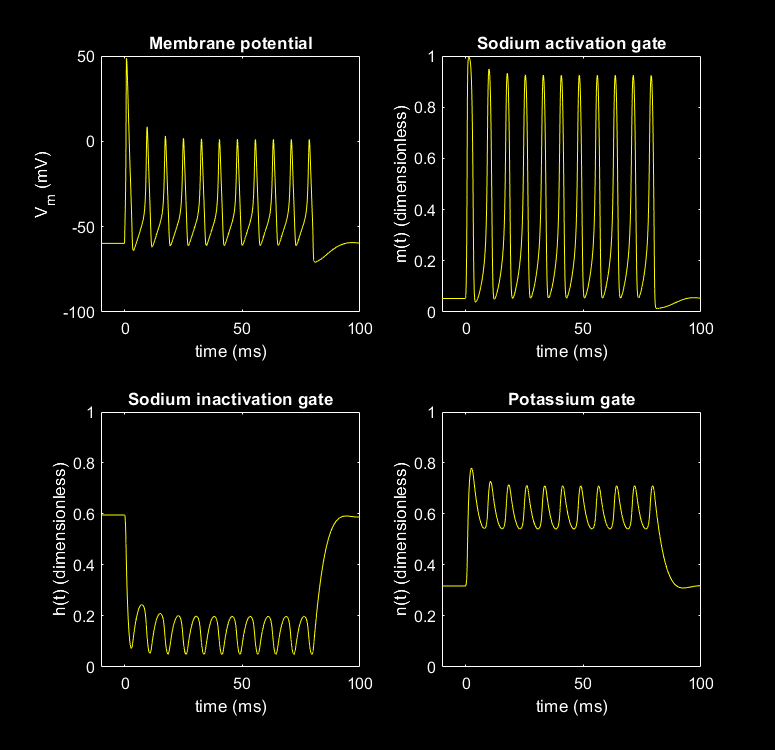

amp1=70;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude = 70

**Number of APs = 11**

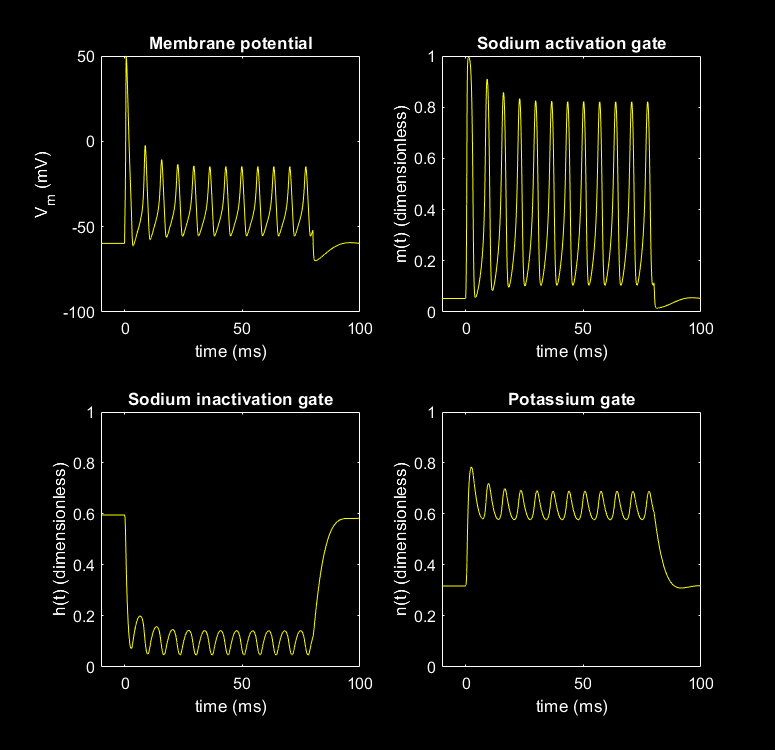

amp1=100;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

Amplitude = 100

**Number of APs = 12**

_

**In summery**

Amplitude = [5; 10; 20; 30; 50; 70; 100];
Number_of_APs = [1; 6; 7; 8; 10; 11; 12];
Table = table(Amplitude,Number_of_APs)

Table = 7×2 table
    Amplitude    Number_of_APs
    _________    _____________

         5             1      
        10             6      
        20             7      
        30             8      
        50            10      
        70            11      
       100            12      


**Plot of action potential frequency as a function of stimulating current amplitude.**

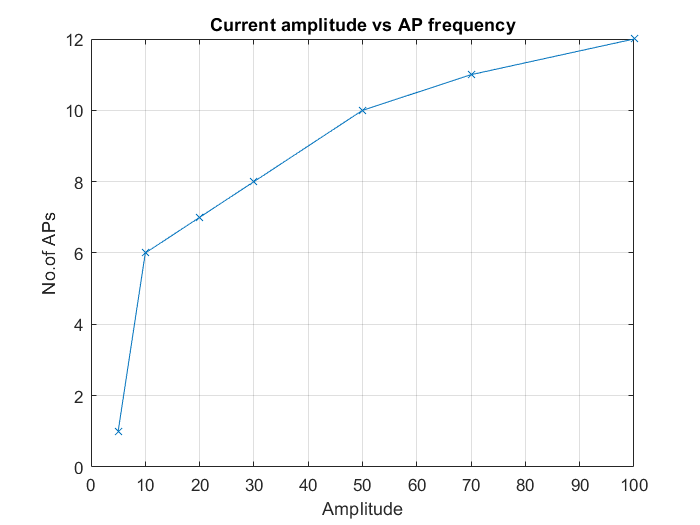

Amplitudes = [5, 10, 20, 30, 50, 70, 100];
No_of_Aps = [1, 6, 7, 8, 10, 11, 12];
figure;
plot(Amplitudes,No_of_Aps,'x-');
xlabel('Amplitude')
ylabel('No.of APs')
title('Current amplitude vs AP frequency')
grid on

By observing above graphs, we can say

- The amplitude of the action potentials decrease when stimulus intensity amplitude increase

- The action potential frequency increase when stimulus intensity amplitude increase

_

_

_

### Question 06

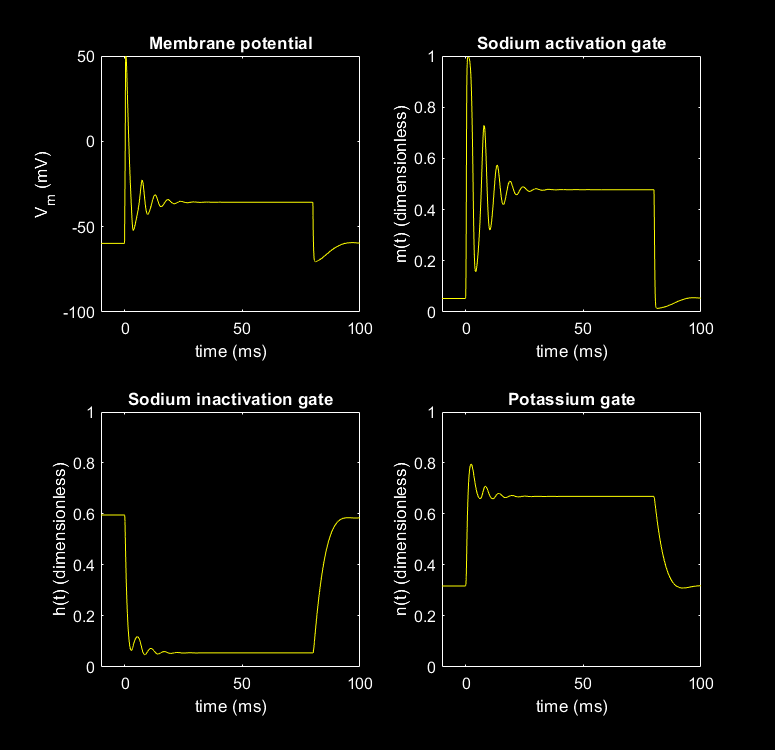

amp1=200;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

When the intensity of the electrical current is increased, an intriguing phenomenon takes place within the neuron. The cell membrane, which normally maintains a stable charge, becomes rapidly depolarized. This depolarization occurs due to the activation of specific voltage-gated sodium channels, denoted as the "m factor." As these channels open, sodium ions rush into the neuron, initiating a remarkable event known as an action potential.

However, the augmented depolarization also exerts an influence on another factor called the "h factor." This factor pertains to the inactivation of sodium channels. As the membrane potential reaches higher levels, the h factor becomes more prominent, causing the inactivation of a portion of the voltage-gated sodium channels. Consequently, fewer sodium channels are available to contribute to the rising phase of the action potential, resulting in a diminished amplitude.

Let us now consider the n factor in the Hodgkin-Huxley equations, which signifies the activation variable for potassium channels. These channels play a crucial role in repolarizing the neuron's membrane potential by allowing potassium ions to exit the cell. However, at extremely high levels of depolarization, the n factor undergoes a significant decrease, causing a decline in the activation of potassium channels. This, in turn, hampers the repolarization process, as the potassium channels remain inactivated and the membrane voltage persists in a depolarized state.

_

_

_

## Temperature dependence

### Question 07

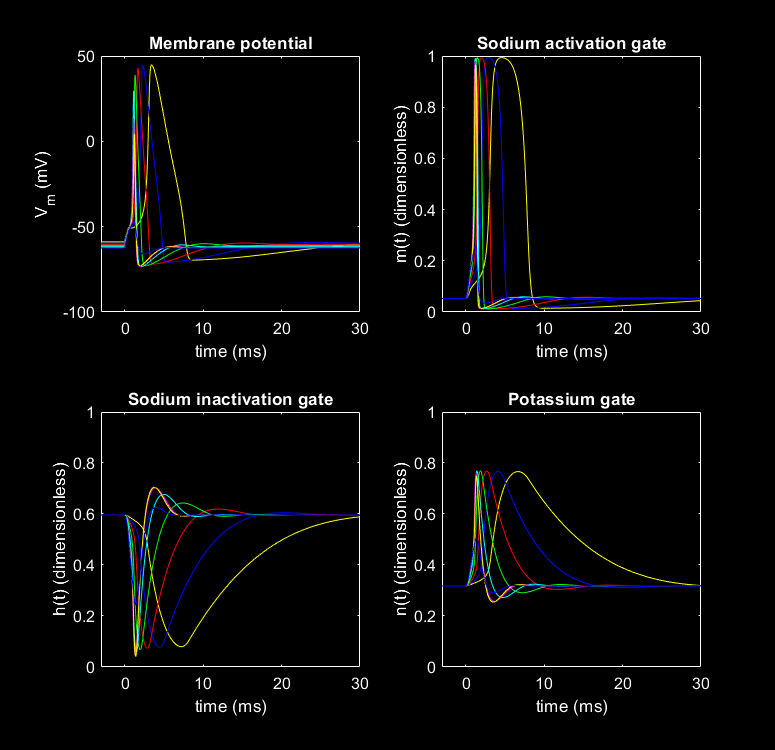

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 0;
hhmplot (0,30,0);

tempc = 5;
hhmplot (0,30,1);

tempc = 10;
hhmplot (0,30,2);

tempc = 15;
hhmplot (0,30,3);

tempc = 20;
hhmplot (0,30,4);

tempc = 24;
hhmplot (0,30,5);

tempc = 25;
hhmplot (0,30,6);

tempc = 26;
hhmplot (0,30,7);

These are the plots that I obtained by using different temperature values. Here we can see clearly the amplitude of the action potential have decrease when increase the temperature.

In general these are the features of the action potential are affected by increasing temperature

- **Amplitude:** The amplitude of the action potential decreases as temperature increases. This is because the rate of inactivation of sodium channels increases with temperature, which means that fewer sodium channels are available to contribute to the rising phase of the action potential.

- **Duration:** The duration of the action potential decreases as temperature increases. This is because the rates of activation and inactivation of sodium and potassium channels both increase with temperature, which means that the action potential has less time to reach its peak and then repolarize.

- **Propagation velocity:** The propagation velocity of the action potential increases as temperature increases. This is because the rates of activation and inactivation of sodium and potassium channels both increase with temperature, which means that the action potential travels more quickly down the axon.

- **Threshold:** The threshold for the initiation of an action potential decreases as temperature increases. This is because the rate of activation of sodium channels increases with temperature, which means that it takes less depolarization to reach the threshold for an action potential to be initiated.